# Diseño Controlador MRAC para aerobalancín.

## Daniel Melo Avila 

## Dylan Ortiz Mayorga 

## Juan Pablo Vallejo Montañez

Construyendo el modelo de la planta con los valores resultantes del proceso de identificacion 

%Parametros de la planta 
clear

%syms th beta d M I k w  s L

d = 58.441*1e-3*0.9; % Distancia desde el centro de masa total hasta el eje de rotacion
M = 0; % Masa total
g = 9.77;
I = 59.270*1e-6*1.55; % centro de masa total
beta = 0.7141542101118331*6.6*I; % Amortiguamiento viscoso
L = 0.129; %+- 1mm distancia del motor al eje de rotacion

k = 0.0203*0.98;

brazoConMotorYBrida = 0.0209; % 20.9g
tajaLapiz = 0.007; % 7g
tornilloYTuerca = 0.0038; % 3.8g
M = brazoConMotorYBrida +tajaLapiz+tornilloYTuerca;
w = M*g

w = 0.3097

Se tiene la planta linealizada en el punto de operación seleccionado $\theta =60\degree$. 

th = pi/6

th = 0.5236


A = [0,1 ; -cos(th)*w*d/(I+(d^2)*M), -beta/(I+(d^2)*M)]

A =          0    1.0000
  -78.5641   -2.4115


B = [0; k*L/(I+(d^2)*M)]

B =          0
   14.2919


C = [1, 0]

C =      1     0


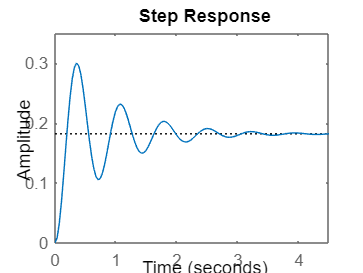

D=0;
inmodel=ss(A,B,C,0);
step(inmodel)

stepinfo(inmodel)

ans = struct with fields:
         RiseTime: 0.1311
    TransientTime: 3.2415
     SettlingTime: 3.2415
      SettlingMin: 0.1053
      SettlingMax: 0.3000
        Overshoot: 64.9338
       Undershoot: 0
             Peak: 0.3000
         PeakTime: 0.3544


damp(inmodel)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.21e+00 + 8.78e+00i     1.36e-01       8.86e+00         8.29e-01    
 -1.21e+00 - 8.78e+00i     1.36e-01       8.86e+00         8.29e-01    



[b,a]=ss2tf(A,B,C,D)

b =          0         0   14.2919


a =     1.0000    2.4115   78.5641


A partir del modelo linealizado se toman sus caracteristicas como la ganacia DC, la frecuencia natural y el amortiguamiento para generar el modelo de referencia. Como requerimientos de diseño se parte de la frecuancia natural del sistema y se desea que la ganancia sea unitaria y el sistema este sobreamortiguado o ciritcamente amortiguado.

Am = [0,1 ; -78.5641, -17.7272]

Am =          0    1.0000
  -78.5641  -17.7272


Bm = [0; 78.5641]

Bm =          0
   78.5641


Cm = [1, 0]

Cm =      1     0


Dm=0;
refmodel=ss(Am,Bm,Cm,Dm)

refmodel =
 
  A = 
           x1      x2
   x1       0       1
   x2  -78.56  -17.73
 
  B = 
          u1
   x1      0
   x2  78.56
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



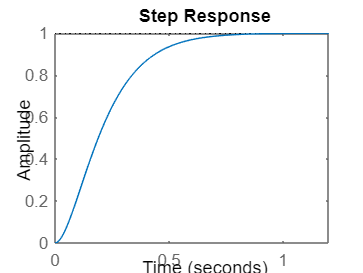

step(refmodel)

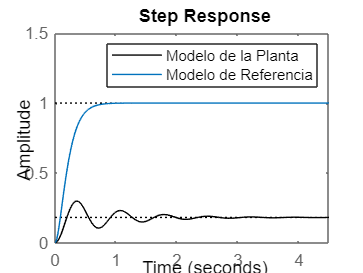


figure()
step(inmodel,'k')
hold on 
step(refmodel)
hold off 
ylim([0 1.5])
legend('Modelo de la Planta', 'Modelo de Referencia')

Con los modelos iniciales y de referencia definidos se procede a definir la forma del controlador nominal.


$$u={\;r\;k}_r +x\;k_x$$


%Condiciones de Acoplamiento 
kr=B\Bm %Resuelve el sistema Bm=B kr

kr = 5.4971

kx=B\(Am-A)

kx =     0.0000   -1.0716



Ac=A+B*kx

Ac =          0    1.0000
  -78.5641  -17.7272


Bc=B*kr

Bc =          0
   78.5641


Cc=C

Cc =      1     0


Dc=D

Dc = 0

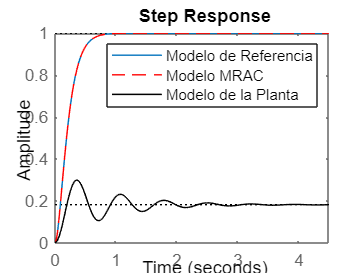

MRACmodel=ss(Ac,Bc,Cc,Dc);


figure()
step(refmodel)
hold on 
step(MRACmodel,'r--')
step(inmodel,"k")
hold off
legend("Modelo de Referencia", "Modelo MRAC","Modelo de la Planta")

**Leyes de Control **

Q = eye(2);
R = 10;
[K, Pmatrix, P] = lqr(refmodel,Q,R);
Pbarra = Pmatrix*[0 1]'

Pbarra =     0.0062
    0.0209


Gx = 100;%0; 0 1];%60*eye(2);
Gr = 0.3;